# Tipos de datos: Caracteres y cadenas

Los *arreglos caracter* (también llamados **char array**) y los *arreglos cadena* (también llamados **string array**) permiten guardar texto. Sin embargo, a diferencia de otros lenguajes de programación, en MATLAB hay una enorme diferencia entre un *arreglo caracter* y un *arreglo cadena*.

Un *arreglo caracter* (**char array**) es una secuencia de caracteres, al igual que un arreglo numérico es una secuencia de números. Un uso típico es almacenar fragmentos cortos de texto como vectores de caracteres, por ejemplo, `c = 'Proyecto Ingenecia'`.

Un *arreglo cadena* (**string array**) es un contenedor para fragmentos de texto. Estos arreglos proporcionan un conjunto de funciones para trabajar con texto como datos.

**Figura 1.** Arreglo caracter VS. Arreglo cadena.

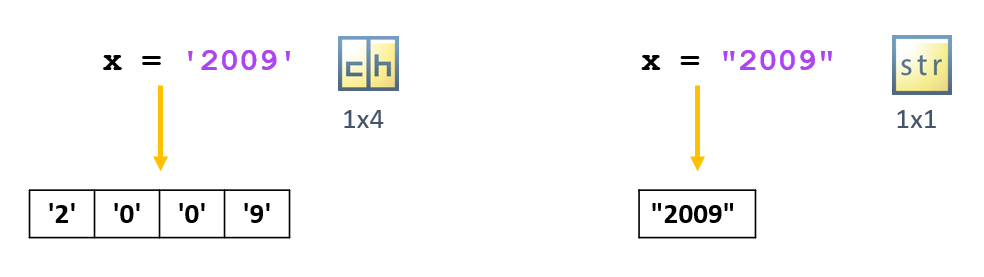

*Tomado de la documentación oficial de MATLAB.*

#### Observación

A partir de la versión R2017a es posible crear cadenas usando comillas dobles, por ejemplo, `str = "Saludos, amigo"`. En versiones anteriores se debe utilizar la función `string` para crear una cadena.

## Funciones de creación y conversión

Existen diversas funciones para crear o convertir diferentes tipos de variables en cadenas o arreglos de caracteres. A continuación se detallan las más usuales.

### Función `char` o `''`

Para crear un arreglo caracter se utiliza la función `char` o apóstrofes `''`.

nombrech='Isacc'

nombrech = 'Isacc'

whos

  Name          Size            Bytes  Class    Attributes

  nombrech      1x5                10  char               



### Función `string` o `""`

Para crear una cadena se utiliza la función `string` o apóstrofes `""`.

nombrestr="Isacc"

nombrestr = "Isacc"

whos

  Name           Size            Bytes  Class     Attributes

  ans            1x1                 8  double              
  nombrestr      1x1               166  string              
  txt            1x1               166  string              



### Funciones `str2double` y `double`

La función `str2double` permite crear un número tipo double a partir de una cadena. Es decir, convierte una cadena en un número.

clear
txt="15"

txt = "15"

str2double(txt)

ans = 15

whos

  Name      Size            Bytes  Class     Attributes

  ans       1x1                 8  double              
  txt       1x1               166  string              



La función `double` es similar a la función `str2double`.

double(txt)

ans = 15

#### Observación

Si la cadena que se ingresa no es un número, entonces las funciones `str2double` y `double` devolverán un `NaN` (**N**ot **a** **N**umber).

numero="Mexico"

numero = "Mexico"

str2double(numero)

ans = NaN

### Función `num2str`

La función `num2str` permite crear un arreglo caracter a partir de un número. Es decir, convierte un número en un arreglo caracter.

clear
edad=15

edad = 15

string(num2str(edad))

ans = "15"

whos

  Name      Size            Bytes  Class     Attributes

  ans       1x1               166  string              
  edad      1x1                 8  double              



## Funciones de concatenación

Existen diversas funciones para concatenar (unir) cadenas o arreglos de caracteres. A continuación se detallan las más usuales.

### Función `plus` o `+`

Las funciones de suma para números permiten concatenar únicamente cadenas.

saludo="Bienvenido.";
usuario="Isaac";
palabras="Ingenecia esta de que estes aqui";
saludo+usuario+palabras

ans = "Bienvenido.IsaacIngenecia esta de que estes aqui"

#### Observación

La función `plus` o `+` sólo sirve con cadenas. Para concatenar arreglos de caracteres se utiliza la función `append`.

### Función `append`

La función `append` permite concatenar cadenas y arreglos de caracteres.

clear
nombre='Isaac ';
apellido='Alpala';
append(nombre,apellido)

ans = 'Isaac Alpala'

whos

  Name          Size            Bytes  Class    Attributes

  ans           1x12               24  char               
  apellido      1x6                12  char               
  nombre        1x6                12  char               



### Función `strcat`

La fución `strcat`, al igual que la función `append`, permite concatenar cadenas y arreglos de caracteres horizontalmente.

strcat(nombre, apellido)

ans = 'IsaacAlpala'

#### ¿Cuál es la diferencia entre la función `append` y la función `strcat`?

Si se concatenan arreglos de caracteres, la función `append` mantiene los espacios en blanco al final del arreglo caracter, mientras que la función `strcat` los elimina.

saludo='Hola ';
nombre='Gabriela ';
append(saludo, nombre)

ans = 'Hola Gabriela '

strcat(saludo,nombre)

ans = 'HolaGabriela'

nombre='Isaac'

nombre = 'Isaac'

apeliido='Alpala'

apeliido = 'Alpala'

whos

  Name          Size            Bytes  Class     Attributes

  ans           1x2               220  string              
  apeliido      1x6                12  char                
  apellido      1x6                12  char                
  nombre        1x5                10  char                
  saludo        1x5                10  char                



char(nombre,apeliido)%=[nombre;apellido]

ans = 2×6 char array
    'Isaac '
    'Alpala'


nombre="Isaac"

nombre = "Isaac"

apeliido="Alpala"

apeliido = "Alpala"

[nombre apellido]

ans = 1×2 string array
    "Isaac"    "Alpala"


M=["12" "0.5 " "13"]

M = 1×3 string array
    "12"    "0.5 "    "13"


str2double(M)

ans =    12.0000    0.5000   13.0000


## Material adicional

- [Caracteres y cadenas](https://www.mathworks.com/help/matlab/characters-and-strings.html)

- [Preguntas frecuentes sobre arreglos cadena](https://www.mathworks.com/help/matlab/matlab_prog/frequently-asked-questions-about-string-arrays.html)